# Calculating Stiffness When Orientation Varies Across the Thickness

Section 8.4.5 discusses the modeling of typical injection molded parts, where the orientation varies across the thickness.  One divides the part into multiple layers, treats the overall part as a laminate of these layers, and uses classical lamination theory to find the stiffness of the laminate.

Classical lamination theory is not explained in the book, but a summary of the theory is available in the documentation folder for this toolkit as **LaminateTheory.pdf**.  

The function `Clayer2laminate` from this toolkit is used to find the stiffness of this type of structure.  This function requires the stiffness tensor $\mathbb{C}$ for each layer, and the $z$ coordinates for each layer, as input.  It returns the laminate stiffness matrices $[A]$, $[B]$ and $[D]$, which relate the midplane strains $\{ \varepsilon^0\}$ and midplane curvatures $\{ \kappa \}$ to the in-plane loads per unit length $\{N\}$ and moments per unit length $\{M\}$ according to


$$   \left\{ \begin{array}{c}
     N_x \\ N_y \\ N_{xy}
   \end{array} \right\}
=
[A] \;
        \left\{ \begin{array}{c}
           \varepsilon^0_{xx}  \\  \varepsilon^0_{yy}  \\  \gamma^0_{xy}
           \end{array} \right\}
+
[B] \;
        \left\{ \begin{array}{c}
           \kappa_{xx}  \\  \kappa_{yy}  \\  \kappa_{xy}
           \end{array} \right\}$$


and


$$   \left\{ \begin{array}{c}
     M_x \\ M_y \\ M_{xy}
   \end{array} \right\}
=
[B] \;
        \left\{ \begin{array}{c}
           \epsilon^0_{xx}  \\  \epsilon^0_{yy}  \\  \gamma^0_{xy}
           \end{array} \right\}
+
[D] \;
        \left\{ \begin{array}{c}
           \kappa_{xx}  \\  \kappa_{yy}  \\  \kappa_{xy}
           \end{array} \right\}$$


See **LaminateTheory.pdf** for details.

`Clayer2laminate` can also return the effective tensile and flexural moduli in the $x$ and $y$ directions.  

Here we'll do the calculations for the long glass fiber/polypropylene composite in Fig. 8.6(c-d) and obtain the values for this material in Table 8.4.

Start by loading the orientation data from a file, and plotting it.

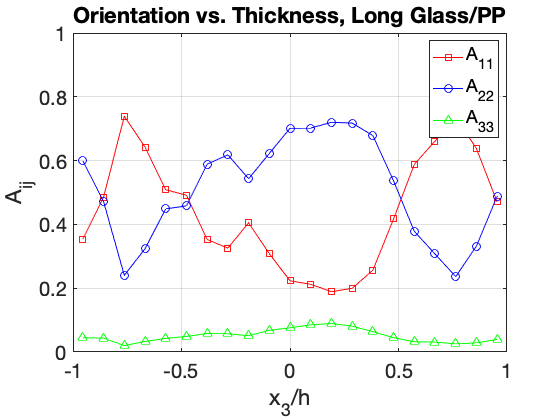

% Load orientation data from a file and plot it
load('AS3I.mat') % Loads A11, A22, A33, A13, z arrays

figure
plot(z, A11, 'rs-', z, A22, 'bo-', z, A33, 'g^-', ...
    'MarkerSize', 8);

set(gca, 'FontSize', 20)
xlabel('x_3/h')
ylabel('A_{ij}')
legend('A_{11}', 'A_{22}', 'A_{33}')
axis([-1 1 0 1])
grid on
title('Orientation vs. Thickness, Long Glass/PP')

We see that this sample has definite skin layers, a thick core, and only moderate alignment in the shell.  

The next step is to find the stiffness tensor for each layer.  We'll follow the same steps used in `OrientationAveragedPropertiesl.mlx`, and same build up an array of the layer stiffness matrices.  We'll create a layer for each orientation data point.

% Find and store the stiffness tensor for each layer

% Material properties
Ef   = 73;    % Fiber modulus, GPa
nuf  = 0.21;  % Fiber Poisson ratio
rhof = 2.55;  % Fiber density, g/cm^3
Em   = 1.325; % Matrix modulus, GPa
num  = 0.42;  % Matrix Poisson ratio
rhom = 0.92;  % Matrix density, g/cm^3
wf   = 0.30;  % Weight fraction fibers
% Fiber volume fraction
vf   = weightFrac2volFrac(wf, rhof, rhom); 
aspect = 100;  % Fiber aspect ratio, l/d
closure = 'N'; % Use the natural closure for properties

% Pseudo-grain stiffness for aligned fibers
% This values is used for all layers
Cp = mori(iso2C(Ef, nuf), iso2C(Em, num), vf, aspect);

% Cycle through the layers, finding and storing
% the orientation-averaged stiffness for each layer
nlayers = length(A11);
Clayer = zeros(6, 6, nlayers); % Storage for stiffness
for i = 1:nlayers
    % Full orientation tensor for this data point
    A = [A11(i), 0,               A13(i); ...
         0,      1-A11(i)-A33(i), 0;      ...
         A13(i), 0,               A33(i)];
    % Stiffness for this layer
    Clayer(:,:,i) = oravg4(Cp, closeA4(A , closure));
end

At this point we could use `C2eng` to find the elastic moduli for each layer, as in Fig. 8.6(c).  However, let's move ahead to get the tensile and flexural moduli.

% Calculate laminated-plate properties
zlayer = -1:(2/nlayers):1;  % z/h values for layers
[A, B, D, Etensile, Eflex] = Clayer2laminate(Clayer, zlayer);

fprintf('Laminated plate properties\n')

Laminated plate properties


fprintf('          E11 (GPa)     E22 (GPa)\n')

          E11 (GPa)     E22 (GPa)


fprintf('Tensile    %5.2f         %5.2f\n', Etensile)

Tensile     4.26          4.79


fprintf('Flexural   %5.2f         %5.2f\n', Eflex)

Flexural    4.94          4.13


This matches the results for the long glass fiber/PP composite in Table 8.4.  In tension, the composite is slightly stiffer in the crossflow direction, $E_{22} > E_{11}$.  This occurs because the core is thick and $A_{22} > A_{11}$ over the core region.  However, in bending the composite is stiffer in the flow direction, $E_{11} > E_{22}$.  The flexural stiffness is affected more by the layers near the upper and lower surfaces, so the shell layers have more influence on bending behavior than the core and the shell layers are oriented more in the flow direction, $A_{11} > A_{22}$.  

Careful readers may notice that the book says this composite has 40% by weight of glass fibers, but the calculations above use 30% by weight.  This was an error by the author.  I've chosen to use the 30% value here in order to match the results in the book.  I the corrected plot and table are in the errata at [https://github.com/charlestucker3/Fundamentals-of-Fiber-Orientation-errata](https://github.com/charlestucker3/Fundamentals-of-Fiber-Orientation-errata) .  